clear; close all; %clc;

% declare variables
e = .9;
rho = 1.0834; % Density at a+*lt
W_MGTO = 700*9.81; % Maximum Gross Takeoff Weight (N) (our aircraft)
W_MGTO = 1000*9.81; % Maximum Gross Takeoff Weight (N) (our aircraft)
b = 20; % wingspan (m)
C_L_max = 2.5; % flapped
%C_L_max = 1.4; % unflapped

W2S_plot_max = 1000;

% define the sink rates given in the spec
V_sc_threshold = convvel(250,"ft/min","m/s"); % threshold
V_sc_objective = convvel(175,"ft/min","m/s"); % objective
r = convlength(250,"ft","m"); % radius of tunr for sink rate requirement


syms Aspect


% drag polar estimation
% confirm c_f value form DG-1000
S_wet_fuse_DG1000 = 19.4; % wetted area of fuselage (m)
S_wet_wing_DG1000 = 34.5; % wetted area of fuselage (m)
S_wet_DG1000 = S_wet_fuse_DG1000 + S_wet_wing_DG1000; % total wetted area (m)
c_f = .00245;
f_DG1000 = EquivalentParasiteArea(c_f, S_wet_DG1000);
S_DG100 = 17.53;
C_D_0_DG1000 = DragCoefficientZeroLift(f_DG1000, S_DG100);


% now generate C_D_0 as a function of aspect ratio

% compute wetteed area
S = b^2/Aspect; % compute planform area
S_wet_wing = S_wet_wing_DG1000 * S / S_DG100; % find wing wetted area
S_wet = S_wet_fuse_DG1000 + S_wet_wing; % find total wetted area
%get C_D_0
f = EquivalentParasiteArea(c_f, S_wet); % find equivalent prasite area
C_D_0 = DragCoefficientZeroLift(f, S); % get Parasite Drag
%C_D_0 = C_D_0 +.015 % flapped C_D_0 increment
C_D_0 = C_D_0 +.008 % morphing wing variant (from morphing du-89 paper)

$$C\_D\_0 = \frac{6694369541209381\,10^{\frac{\log\left(\frac{32664723271291869375}{3854887766982656\,\mathrm{Aspect}}+\frac{73471957271079683}{351843720888320}\right)}{\log\left(10\right)}-\frac{1470948232708613}{562949953421312}}\,\mathrm{Aspect}}{28823037615171174400}+\frac{1}{125}$$




Aspects = linspace(1,50,100);
C_D_0 = double(subs(C_D_0, Aspect, Aspects));



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sink rate requirements
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
C_L = C_L_max; % assume that the C_L_max is as close maximising (C_L^(3/2)/C_D) as possilbe

W2S_sink_threshold = W2S_SinkRateCircle(V_sc_threshold, r, C_D_0, C_L, Aspects, e, rho);
W2S_sink_objective = W2S_SinkRateCircle(V_sc_objective, r, C_D_0, C_L, Aspects, e, rho);

ylim([0,50]);

% plot atainable wing loading line
hold on;

% plot sink rate constraints using fill regions
boundrayEdges_Ycoords = [Aspects, fliplr(Aspects)];
threshold_boundrayEdges_Xcoords = [ones(size(W2S_sink_threshold))*1000, fliplr(W2S_sink_threshold)];
objective_boundrayEdges_Ycoords = [ones(size(W2S_sink_objective))*1000, fliplr(W2S_sink_objective)];

fill(objective_boundrayEdges_Ycoords, boundrayEdges_Ycoords, [1,1,0],"FaceAlpha",.20)
fill(threshold_boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0],"FaceAlpha",.30)
xlim([0,900]);

V_sc_requirement = [25];
% V_sc_objective = [25];

C_L_minSink = 2.5; % TODO: verify this

% objective
%plotSinkRateLimits(V_sc_objective, r, C_D_0, C_L_minSink, Aspects, e, rho, [1,1,0], .2)
% requirement
%plotSinkRateLimits(V_sc_requirement, r, C_D_0, C_L_minSink, Aspects, e, rho, [1,0,0], .3)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% lift to drag rqueirements
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% requirement limits
L2D_requirement = [25];
V_requirement = [convvel(45,"kts","m/s")];

% objective limits
L2D_objective = [25, 30];
V_objective = [convvel(70,"kts","m/s"), convvel(50,"kts","m/s")];

% ploting parameters
Alpha_requirement = .3; Colour_requirement = [1,0,0]; % formatting for requirements
Alpha_objective = .2; Colour_objective = [1,1,0]; % fromatting for objectives
plotStallLine = true;
W2S_plot_max = 1000;

% plot objectives
for i = 1:length(L2D_objective)
    L2D = L2D_objective(i);
    V = V_objective(i);
    plotL2DLimits(L2D, V, C_D_0, C_L_max, Aspects, e, rho, Colour_objective, Alpha_objective, plotStallLine, W2S_plot_max);
end


% plot requirements
for i = 1:length(L2D_requirement)
    L2D = L2D_requirement(i);
    V = V_requirement(i);
    plotL2DLimits(L2D, V, C_D_0, C_L_max, Aspects, e, rho, Colour_requirement, Alpha_requirement, plotStallLine, W2S_plot_max);
end

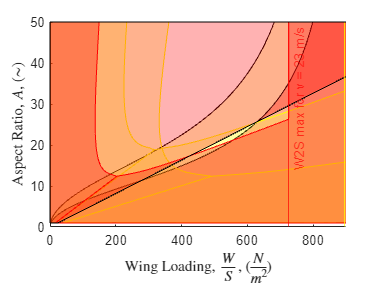


xlim([0,900]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Span Requirement
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% compute aspectratio  wingloanding relationship for b=20
S_possible = b^2 ./ Aspects;
W2S_possible = W_MGTO ./ S_possible;
exclude_Apsect2W2S = [zeros(size(Aspects)), fliplr(W2S_possible)];
% plot aspectratio  wingloanding relationship for b=20
hold on;
fill(exclude_Apsect2W2S, boundrayEdges_Ycoords, Colour_requirement,"FaceAlpha",Alpha_requirement);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% plot settings
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

xlabel("Wing Loading, $\frac{W}{S}$, $(\frac{N}{m^2})$",Interpreter="latex");
ylabel("Aspect Ratio, $A$, $(\sim)$",Interpreter="latex");
xlim([0,900]); ylim([0,50]);

function plotSinkRateLimits(V_sc, r, C_D_0, C_L_minSink, Aspects, e, rho, Colour, Alpha)
    % compute the constraint
    W2S_sink = W2S_SinkRateCircle(V_sc, r, C_D_0, C_L_minSink, Aspects, e, rho);

    % compute edges of contrained region
    boundrayEdges_Ycoords = [Aspects, fliplr(Aspects)];
    boundrayEdges_Xcoords = [ones(size(W2S_sink))*1000, fliplr(W2S_sink)];

    % plot contrained region
    fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, Colour, "FaceAlpha",Alpha)
end

% Lift to Drag Limits
function plotL2DLimits(L2D, V, C_D_0, C_L_max, Aspects, e, rho, Colour, Alpha, plotStallLine, W2S_plot_max)
    % compute the requirement boundaries
    W2Ss = W2S_LiftToDragAtSpeed(L2D, V, C_D_0, C_L_max, Aspects, e, rho); % Objective: L/D = 25 at no less that 70kts
    
    % compute edges of contrained region
    boundrayEdges_Ycoords = [Aspects, fliplr(Aspects)];
    exclude_upper = [zeros(size(Aspects)), fliplr(W2Ss(1,:))]; % upper bound
    exclude_lower = [W2S_plot_max* ones(size(Aspects)), fliplr(W2Ss(2,:))]; % lower bound
    
    %plot the boundaries
    fill(exclude_upper, boundrayEdges_Ycoords, Colour, "FaceAlpha",Alpha, "EdgeColor",Colour); hold on;
    fill(exclude_lower, boundrayEdges_Ycoords, Colour, "FaceAlpha",Alpha, "EdgeColor",Colour);
    
    % optional plot stall line
    if plotStallLine
        syms wingloading
        stall = double(solve(wingloading*2/(rho*V^2) == C_L_max, wingloading));
        xline(stall,"-",sprintf("W2S max for v = %.2g m/s",V),"Color",Colour);
    end
end
